# 电动机机械特性⚙️

    使用MATLAB来绘制电动机固有机械特性和人为机械特性。直流电动机的机械特性可以使用这样的公示来表示，


$$n=\frac{U-I_a(R_a+R)}{C_e\Phi}
=\frac{U}{C_e\Phi}-\frac{R_a+R}{C_e C_t \Phi^2}T
=n_0-\beta T$$


常用的人为机械特性有：

- 降电压调速

- 串电阻调速

- 弱磁升速

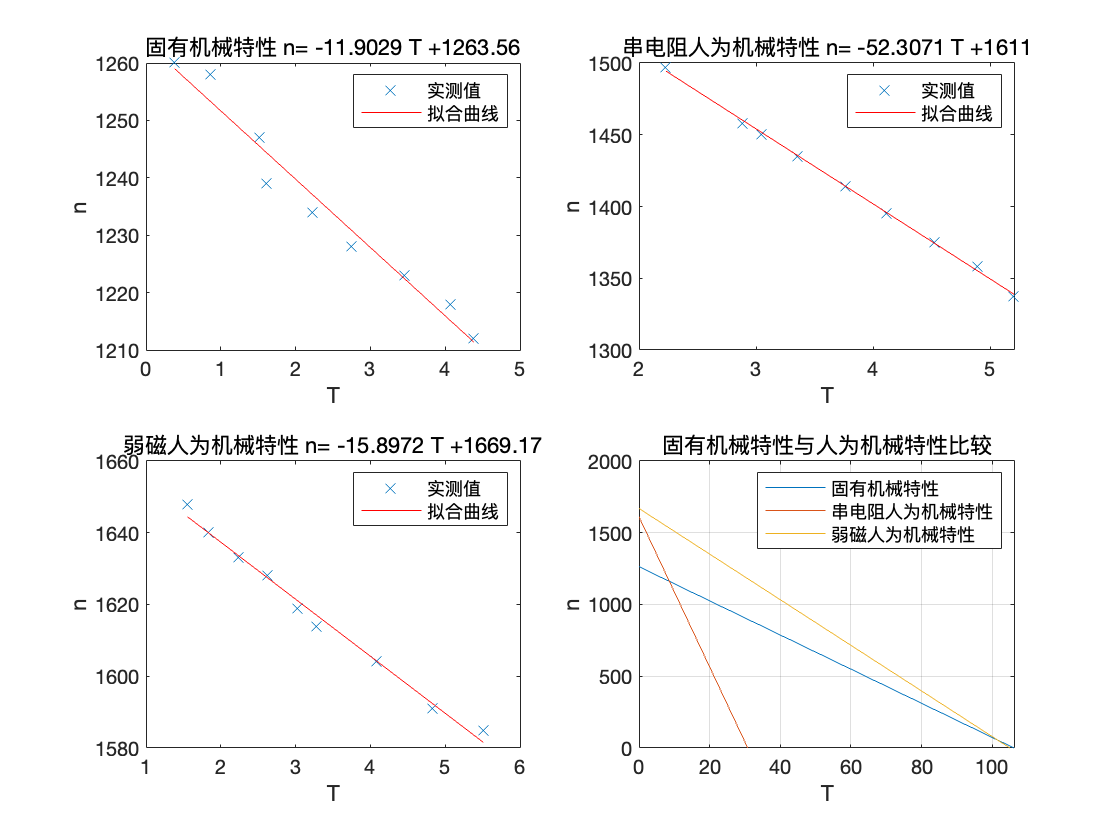

name=["固有机械特性","串电阻人为机械特性","弱磁人为机械特性"];
N=3;
figure();
for i=1:N
    num=xlsread('data.xlsx',i);
    n=num(2,:);
    T=num(4,:);
    p=polyfit(T,n,1);
    f=polyval(p,T);
    subplot(2,2,i);
    plot(T,n,'x',T,f,'r-');
    legend("实测值","拟合曲线");
    str=sprintf(' n= %g T +%g ',p(1),p(2));
    title(strcat(name(i),str));
    xlabel('T');
    ylabel('n');
    subplot(2,2,4);
    T2=[0,T,-p(2)/p(1)];
    n2=polyval(p,T2);
    plot(T2,n2,'DisplayName',name(i));
    hold on;
end
subplot(2,2,4);
title("固有机械特性与人为机械特性比较");
grid
    xlabel('T');
    ylabel('n');
legend
hold off